participants(1) = load("results_p05.mat")

p_list = struct with fields:
    participant_results: [3×1 struct]


participants(2) = load("results_p06.mat")

p_list = 1×2 struct array with fields:
    participant_results


participants(3) = load("results_p07.mat")

p_list = 1×3 struct array with fields:
    participant_results


## Intended Movement Slopes Across Tasks: Control

t1_slopes = [];
t2_slopes = [];
t3_slopes = [];
for i=1:length(participants)
    t1_slopes = [t1_slopes; participants(i).task_results(1).rmse_slopes.ctrl.int_a(1); participants(i).participant_results(1).rmse_slopes.ctrl.int_b(1)];
    t2_slopes = [t2_slopes; participants(i).task_results(2).rmse_slopes.ctrl.int_a(1); participants(i).participant_results(2).rmse_slopes.ctrl.int_b(1)];
    t3_slopes = [t3_slopes; participants(i).task_results(3).rmse_slopes.ctrl.int_a(1); participants(i).participant_results(3).rmse_slopes.ctrl.int_b(1)];
end

#### Histogram to look for outliers

tlo = tiledlayout(1,3);
nexttile
hist(t1_slopes)
isoutlier(t1_slopes, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


nexttile
hist(t2_slopes)
isoutlier(t2_slopes, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


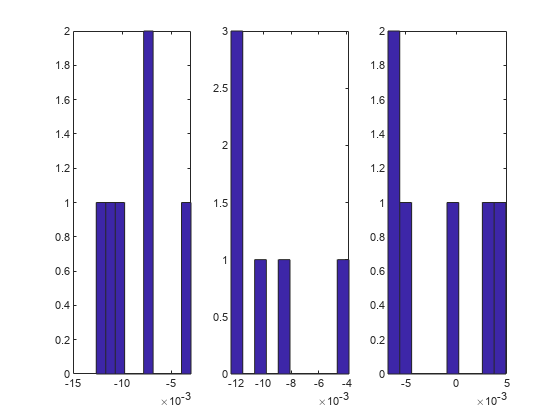

nexttile
hist(t3_slopes)

isoutlier(t3_slopes, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


#### AD Test for Parametric Data

Null Hypothesis: Data is from a population with normal distribution. 1: reject null hypothesis at 5% significance. 0: fail to reject null

adtest(t1_slopes)

ans = logical
   0


adtest(t2_slopes)

ans = logical
   0


adtest(t3_slopes)

ans = logical
   0


#### Parametric 2-group Paired Comparison: Adaptive vs Non-Adaptive Learning Rate for Intended Movements

Null Hypothesis: data in x-y comes from a normal distribution with a mean of zero. 0: fail to reject null

[h, p] = ttest(t2_slopes, t3_slopes)

h = 1

p = 0.0090

t2_mean_xpar_int = mean(t2_slopes)

t2_mean_xpar_int = -0.0098

t2_sem_xpar_int = std(t2_slopes)/sqrt(length(t2_slopes))

t2_sem_xpar_int = 0.0014

t3_mean_xpar_int = mean(t3_slopes)

t3_mean_xpar_int = -0.0019

t3_sem_xpar_int = std(t3_slopes)/sqrt(length(t2_slopes))

t3_sem_xpar_int = 0.0020

## Non-Intended Movement Slopes Across Tasks: Control

t1_slopes = [];
t2_slopes = [];
t3_slopes = [];
for i=1:length(participants)
    t1_slopes = [t1_slopes; participants(i).participant_results(1).rmse_slopes.ctrl.xint_a(1); participants(i).participant_results(1).rmse_slopes.ctrl.xint_b(1)];
    t2_slopes = [t2_slopes; participants(i).participant_results(2).rmse_slopes.ctrl.xint_a(1); participants(i).participant_results(2).rmse_slopes.ctrl.xint_b(1)];
    t3_slopes = [t3_slopes; participants(i).participant_results(3).rmse_slopes.ctrl.xint_a(1); participants(i).participant_results(3).rmse_slopes.ctrl.xint_b(1)];
end

#### Histogram to look for outliers

tlo = tiledlayout(1,3);
nexttile
hist(t1_slopes)
isoutlier(t1_slopes, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


nexttile
hist(t2_slopes)
isoutlier(t2_slopes, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


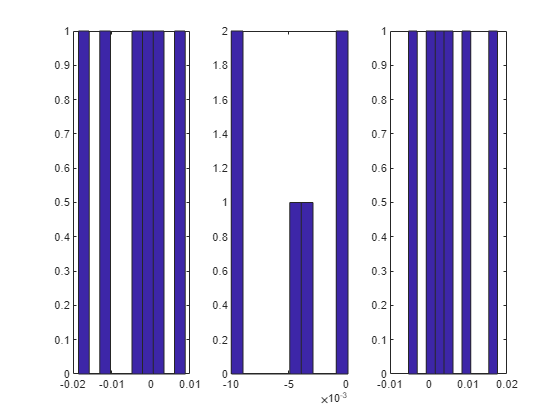

nexttile
hist(t3_slopes)

isoutlier(t3_slopes, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


#### AD Test for Parametric Data

Null Hypothesis: Data is from a population with normal distribution. 1: reject null hypothesis at 5% significance. 0: fail to reject null

adtest(t1_slopes)

ans = logical
   0


adtest(t2_slopes)

ans = logical
   0


adtest(t3_slopes)

ans = logical
   0


#### Parametric 2-group Paired Comparison: Adaptive vs Non-Adaptive Learning Rate for Non-Intended Movements

Null Hypothesis: data in x-y comes from a normal distribution with a mean of zero. 0: fail to reject null

[h, p] = ttest(t2_slopes, t3_slopes)

h = 1

p = 0.0194

t2_mean_xpar_xint = mean(t2_slopes)

t2_mean_xpar_xint = -0.0046

t2_sem_xpar_xint = std(t2_slopes)/sqrt(length(t2_slopes))

t2_sem_xpar_xint = 0.0017

t3_mean_xpar_xint = mean(t3_slopes)

t3_mean_xpar_xint = 0.0050

t3_sem_xpar_xint = std(t3_slopes)/sqrt(length(t3_slopes))

t3_sem_xpar_xint = 0.0032

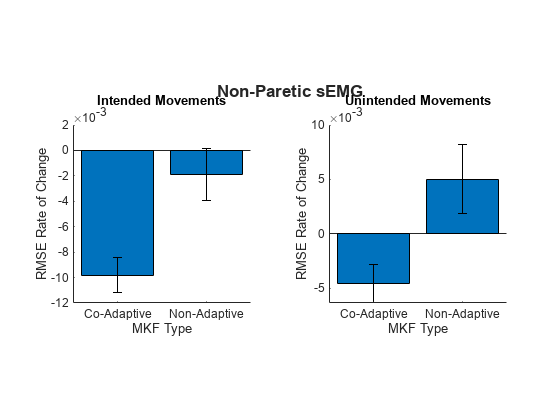

figure
tlo = tiledlayout(1,2);
nexttile
x=1:2;
data = [t2_mean_xpar_int t3_mean_xpar_int]';
errhigh = [t2_sem_xpar_int, t3_sem_xpar_int];
errlow  = errhigh;

bar(x,data)                

hold on

er = errorbar(x,data,errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off
box off
axis square

xticklabels({'Co-Adaptive', 'Non-Adaptive'})
xlabel("MKF Type")
ylabel('RMSE Rate of Change')
title({"Intended Movements",""})
nexttile
x=1:2;
data = [t2_mean_xpar_xint t3_mean_xpar_xint]';
errhigh = [t2_sem_xpar_xint, t3_sem_xpar_xint];
errlow  = errhigh;

bar(x,data)                

hold on

er = errorbar(x,data,errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off
box off
axis square

xticklabels({'Co-Adaptive', 'Non-Adaptive'})
xlabel("MKF Type")
ylabel('RMSE Rate of Change')
title({"Unintended Movements",""})
title(tlo, {"Non-Paretic sEMG",""}, FontWeight='bold')

## Intended Movement Slopes Across Tasks: Experimental

t1_slopes = [];
t2_slopes = [];
t3_slopes = [];
for i=1:length(participants)
    t1_slopes = [t1_slopes; participants(i).participant_results(1).rmse_slopes.expl.int_a(1); participants(i).participant_results(1).rmse_slopes.expl.int_b(1)];
    t2_slopes = [t2_slopes; participants(i).participant_results(2).rmse_slopes.expl.int_a(1); participants(i).participant_results(2).rmse_slopes.expl.int_b(1)];
    t3_slopes = [t3_slopes; participants(i).participant_results(3).rmse_slopes.expl.int_a(1); participants(i).participant_results(3).rmse_slopes.expl.int_b(1)];
end

#### Histogram to look for outliers

tlo = tiledlayout(1,3);
nexttile
hist(t1_slopes)
isoutlier(t1_slopes, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


nexttile
hist(t2_slopes)
isoutlier(t2_slopes, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


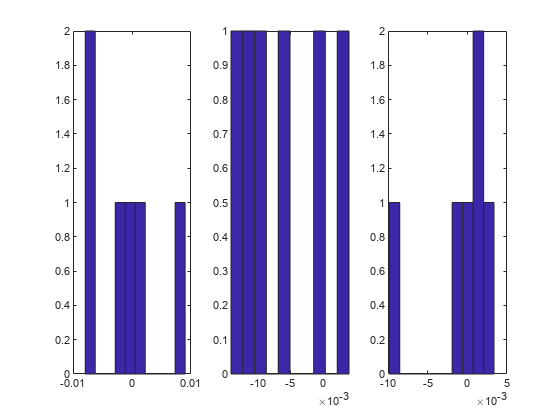

nexttile
hist(t3_slopes)

t3_outliers = isoutlier(t3_slopes, 'quartiles')

t3_outliers = 6×1 logical array
   0
   0
   1
   0
   0
   0


#### AD Test for Parametric Data

Null Hypothesis: Data is from a population with normal distribution. 1: reject null hypothesis at 5% significance. 0: fail to reject null

adtest(t1_slopes)

ans = logical
   0


adtest(t2_slopes)

ans = logical
   0


adtest(t3_slopes)

ans = logical
   0


#### Parametric 2-group Paired Comparison: Adaptive vs Non-Adaptive Learning Rate for Intended Movements

Null Hypothesis: data in x-y comes from a normal distribution with a mean of zero. 0: fail to reject null

[h, p] = ttest(t2_slopes(t3_outliers~=1), t3_slopes(t3_outliers~=1))

h = 1

p = 0.0163

t2_mean_par_int = mean(t2_slopes(t3_outliers~=1))

t2_mean_par_int = -0.0081

t2_sem_par_int = std(t2_slopes(t3_outliers~=1)) / sqrt(length(t2_slopes(t3_outliers~=1)))

t2_sem_par_int = 0.0025

t3_mean_par_int = mean(t3_slopes(t3_outliers~=1))

t3_mean_par_int = 0.0011

t3_sem_par_int = std(t3_slopes(t3_outliers~=1)) / sqrt(length(t3_slopes(t3_outliers~=1)))

t3_sem_par_int = 8.1043e-04

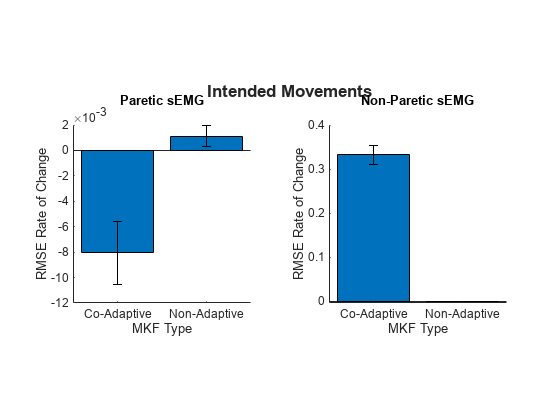

figure
tlo = tiledlayout(1,2);
nexttile
x=1:2;
data = [t2_mean_par_int t3_mean_par_int]';
errhigh = [t2_sem_par_int, t3_sem_par_int];
errlow  = errhigh;

bar(x,data)                

hold on

er = errorbar(x,data,errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off
box off
axis square

xticklabels({'Co-Adaptive', 'Non-Adaptive'})
xlabel("MKF Type")
ylabel('RMSE Rate of Change')
title({"Paretic sEMG",""})
nexttile
x=1:2;
data = [t2_mean_xpar_int t3_mean_xpar_int]';
errhigh = [t2_sem_xpar_int, t3_sem_xpar_int];
errlow  = errhigh;

bar(x,data)                

hold on

er = errorbar(x,data,errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off
box off
axis square

xticklabels({'Co-Adaptive', 'Non-Adaptive'})
xlabel("MKF Type")
ylabel('RMSE Rate of Change')
title({"Non-Paretic sEMG",""})
title(tlo, {"Intended Movements",""}, FontWeight='bold')

#### T2 vs T1 Par Int

[h, p] = ttest(t2_slopes, t1_slopes)

h = 0

p = 0.1183

## Non-Intended Movement Slopes Across Tasks: Experimental

t1_slopes = [];
t2_slopes = [];
t3_slopes = [];
for i=1:length(participants)
    t1_slopes = [t1_slopes; participants(i).participant_results(1).rmse_slopes.expl.xint_a(1); participants(i).participant_results(1).rmse_slopes.expl.xint_b(1)];
    t2_slopes = [t2_slopes; participants(i).participant_results(2).rmse_slopes.expl.xint_a(1); participants(i).participant_results(2).rmse_slopes.expl.xint_b(1)];
    t3_slopes = [t3_slopes; participants(i).participant_results(3).rmse_slopes.expl.xint_a(1); participants(i).participant_results(3).rmse_slopes.expl.xint_b(1)];
end

#### Histogram to look for outliers

tlo = tiledlayout(1,3);
nexttile
hist(t1_slopes)
t1_outliers = isoutlier(t1_slopes, 'quartiles')

t1_outliers = 6×1 logical array
   0
   0
   1
   0
   0
   0


nexttile
hist(t2_slopes)
isoutlier(t2_slopes, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


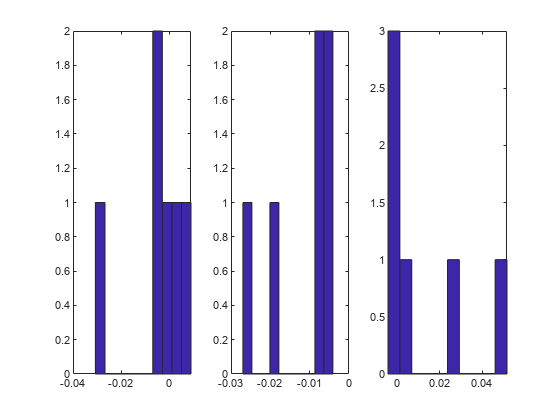

nexttile
hist(t3_slopes)

isoutlier(t3_slopes, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


#### AD Test for Parametric Data

Null Hypothesis: Data is from a population with normal distribution. 1: reject null hypothesis at 5% significance. 0: fail to reject null

adtest(t1_slopes)

ans = logical
   0


adtest(t2_slopes)

ans = logical
   0


adtest(t3_slopes)

ans = logical
   1


#### Non-Parametric 2-group Paired Comparison: Adaptive vs Non-Adaptive Learning Rate for Non-Intended Movements

Null Hypothesis: data has zero median for the difference between paired samples. 0: fail to reject null

[p, h] = signrank(t2_slopes, t3_slopes)

p = 0.0625

h = logical
   0


mean(t2_slopes)

ans = -0.0115

std(t2_slopes)

ans = 0.0091

mean(t3_slopes)

ans = 0.0119

std(t3_slopes)

ans = 0.0222


[h, p] = ttest(t2_slopes(t1_outliers~=1), t1_slopes(t1_outliers~=1))

h = 0

p = 0.0830